clear variables

T = 50 * ( 1 / 50 );
Fs = 8500;
dt = 1 / Fs;
t = 0 : dt : T-dt;
f = 200;

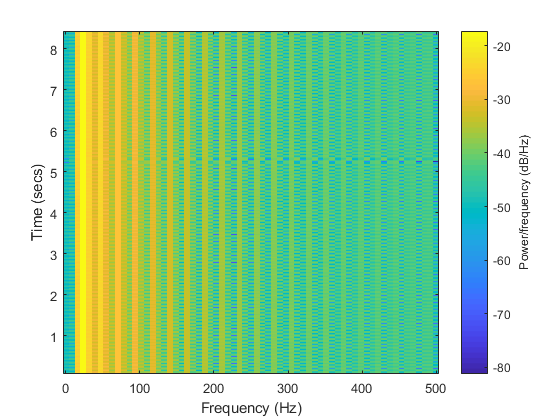

saw = sawtooth(2 * pi * f * t);

spectrogram(saw, 128, 120, 128, 1e3);

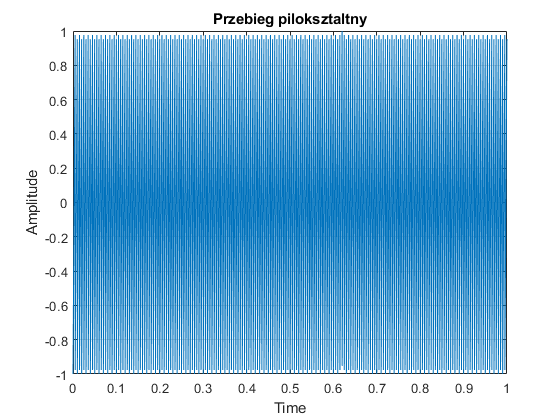


plot(t, saw);
grid on;
ylabel('Amplitude');
xlabel('Time');
title('Przebieg piloksztaltny');


sawPlay = audioplayer(saw, Fs);

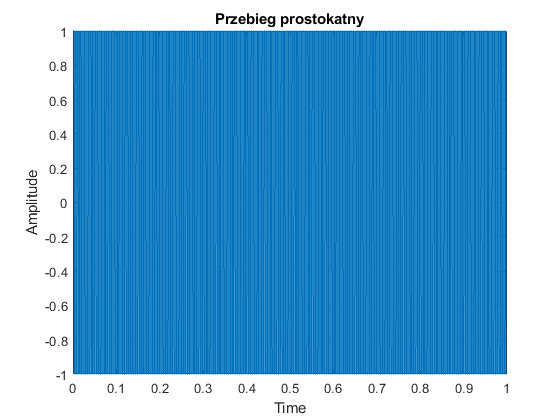

sq = square(2 * pi * f * t);

plot(t, sq);
grid on;
ylabel('Amplitude');
xlabel('Time');
title('Przebieg prostokatny');


sqPlay = audioplayer(sq, Fs);

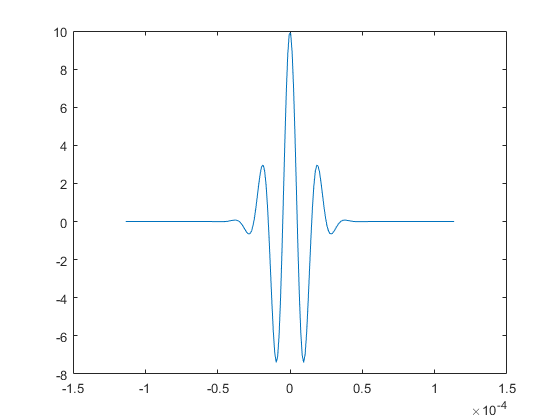

tc = gauspuls('cutoff', 50e3, 0.6, [], -40);
t = -3 * tc : 1e-6 : 3 * tc;
gaus = 10 * gauspuls(t, 50e3, 0.6);

plot(t, gaus);


gausPlay = audioplayer(gaus, Fs);

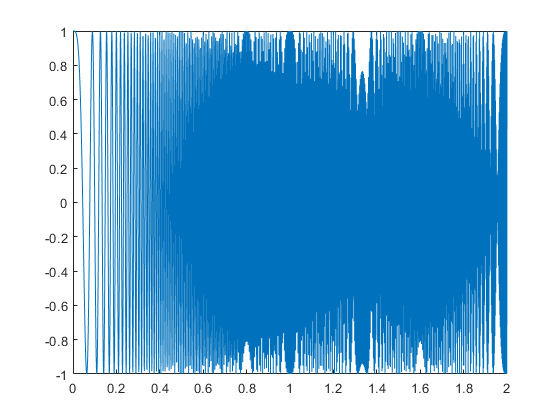

t = 0:1/1e3:2;
ch = chirp(t,0,1,250);

plot(t, ch);


chPlay = audioplayer(ch, Fs);

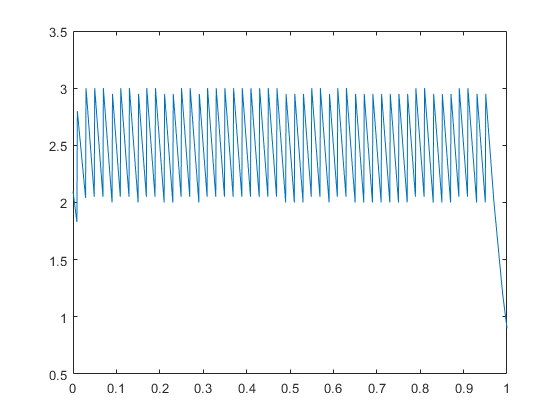

t = 0 : 1/1e3 : 1;         % 1 kHz sample freq for 1 s
d = 0 : 1/50 : 1;           % 3 Hz repetition frequency
y = pulstran(t,d,'tripuls',0.1,-1);

plot(t, y);


trainPlayer = audioplayer(y, 1000);

 playblocking(sawPlay);
playblocking(sqPlay);
playblocking(gausPlay);
playblocking(chPlay);
playblocking(trainPlayer);